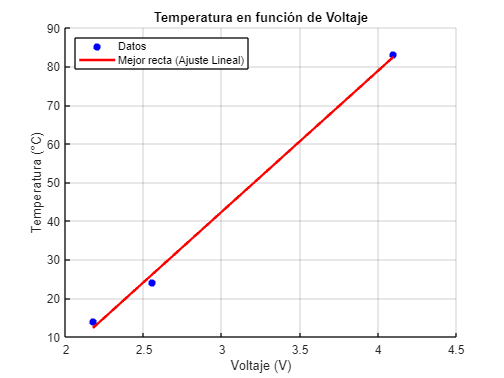

% Datos de los puntos específicos
voltaje = [2.175 2.555 4.1]; % Voltaje en V
temperatura = [14 24 83]; % Temperatura en °C

% Ajuste de la recta con regresión lineal usando solo estos 3 puntos
p = polyfit(voltaje, temperatura, 1); % Ajuste lineal

% Crear valores para graficar la recta ajustada
voltaje_fit = linspace(min(voltaje), max(voltaje), 100); % Valores para la línea
temperatura_fit = polyval(p, voltaje_fit); % Evaluar la recta ajustada

% Graficar los puntos
figure;
scatter(voltaje, temperatura, 'b', 'filled');
hold on;

% Graficar la recta de mejor ajuste
plot(voltaje_fit, temperatura_fit, 'r-', 'LineWidth', 2);

% Configuración del gráfico
title('Temperatura en función de Voltaje');
xlabel('Voltaje (V)');
ylabel('Temperatura (°C)');
legend('Datos', 'Mejor recta (Ajuste Lineal)', 'Location', 'NorthWest');
grid on;
hold off;


% Mostrar los coeficientes de la recta
disp('Coeficientes de la recta:');

Coeficientes de la recta:


disp(['Pendiente: ', num2str(p(1))]);

Pendiente: 36.5205


disp(['Intercepto: ', num2str(p(2))]);

Intercepto: -67.1586
